## Parametric Sweep for HTSAAM Machine

### Main Machine Parameters

%Clear all
clc;
clear all

%Optimization Outputs
machine.Npole = 240;
%stator.current_density = 6 %solution(2);     % Current Density (A/mm^2)
%stator.coil_thickness = 30/1000;
%stator.coil_width_to_coil_pitch_ratio = 0.4;

Parameter Sweep adjustment

sweep.min = 60;
sweep.max = 180;
sweep.number = 30;

%Create output matrix;
output = zeros (5*sweep.number,6);
for k=1:5

   HTS.R_mean = 1.5 + 0.5*k;

for i=1:sweep.number

    machine.Npole = sweep.min + (i-1)*((sweep.max - sweep.min)/sweep.number);
    main;
    output ((k-1)*30+i,1) = 2*HTS.R_mean; %Diameter
    output ((k-1)*30+i,2) = machine.Npole;
    output ((k-1)*30+i,3) = machine.P_output/1e6;  %MW
    output ((k-1)*30+i,4) = machine.efficiency;
    output ((k-1)*30+i,5) = stator.mass/1000; %t
    output ((k-1)*30+i,6) = HTS.length_total/1000; %km


end
end



## Results

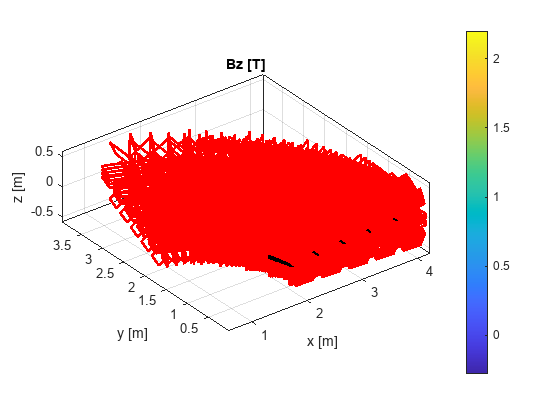


tiledlayout("flow")  %Subplot

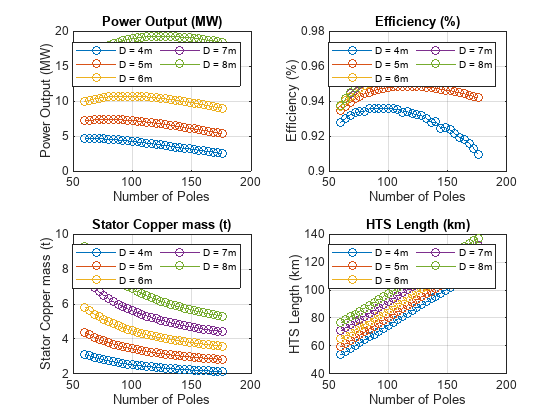

nexttile
plot(output(:,1), output(:,2),'-o')
title("Power Output (MW)")
xlabel('Coil width to Pole Pitch Ratio') 
ylabel('Power Output (MW)') 
grid on

nexttile
plot(output(:,1), output(:,3)*100,'-o')
title("Efficiency (%)")
xlabel('Coil width to Pole Pitch Ratio') 
ylabel('Efficiency (%)') 
grid on

nexttile
plot(output(:,1), output(:,4),'-o')
title("Stator Copper mass (t)")
xlabel('Coil width to Pole Pitch Ratio') 
ylabel('Stator Copper mass (t)') 
grid on


nexttile
plot(output(:,1), output(:,5),'-o')
title("Maximum Flux Density (T)")
xlabel('Coil width to Pole Pitch Ratio') 
ylabel('Maximum Flux Density (T)') 
grid on

tiledlayout("flow")  %Subplot

nexttile
plot(output(1:30,2), output(1:30,3),'-o', 'DisplayName', 'D = 4m') 
hold on
plot(output(31:60,2), output(31:60,3),'-o', 'DisplayName', 'D = 5m')
plot(output(61:90,2), output(61:90,3),'-o', 'DisplayName', 'D = 6m')
plot(output(91:120,2), output(91:120,3),'-o', 'DisplayName', 'D = 7m')
plot(output(121:150,2), output(121:150,3),'-o', 'DisplayName', 'D = 8m')
My_LGD = legend;
My_LGD.NumColumns = 2;    % Show legends in two lines
title("Power Output (MW)")
xlabel('Number of Poles') 
ylabel('Power Output (MW)') 
grid on

nexttile
plot(output(1:30,2), output(1:30,4),'-o', 'DisplayName', 'D = 4m') 
hold on
plot(output(31:60,2), output(31:60,4),'-o', 'DisplayName', 'D = 5m')
plot(output(61:90,2), output(61:90,4),'-o', 'DisplayName', 'D = 6m')
plot(output(91:120,2), output(91:120,4),'-o', 'DisplayName', 'D = 7m')
plot(output(121:150,2), output(121:150,4),'-o', 'DisplayName', 'D = 8m')
My_LGD = legend;
My_LGD.NumColumns = 2;    % Show legends in two lines
title("Efficiency (%)")
xlabel('Number of Poles') 
ylabel('Efficiency (%)') 
grid on

nexttile
plot(output(1:30,2), output(1:30,5),'-o', 'DisplayName', 'D = 4m') 
hold on
plot(output(31:60,2), output(31:60,5),'-o', 'DisplayName', 'D = 5m')
plot(output(61:90,2), output(61:90,5),'-o', 'DisplayName', 'D = 6m')
plot(output(91:120,2), output(91:120,5),'-o', 'DisplayName', 'D = 7m')
plot(output(121:150,2), output(121:150,5),'-o', 'DisplayName', 'D = 8m')
My_LGD = legend;
My_LGD.NumColumns = 2;    % Show legends in two lines
title("Stator Copper mass (t)")
xlabel('Number of Poles') 
ylabel('Stator Copper mass (t)') 
grid on


nexttile
plot(output(1:30,2), output(1:30,6),'-o', 'DisplayName', 'D = 4m') 
hold on
plot(output(31:60,2), output(31:60,6),'-o', 'DisplayName', 'D = 5m')
plot(output(61:90,2), output(61:90,6),'-o', 'DisplayName', 'D = 6m')
plot(output(91:120,2), output(91:120,6),'-o', 'DisplayName', 'D = 7m')
plot(output(121:150,2), output(121:150,6),'-o', 'DisplayName', 'D = 8m')
My_LGD = legend;
My_LGD.NumColumns = 2;    % Show legends in two lines
title("HTS Length (km)")
xlabel('Number of Poles') 
ylabel('HTS Length (km)') 
grid on